# **Nonlinear seismic response of a moment resisting frame**

Original examples file: [OpenSeesPy-Examples/NLSMRF.ipynb at master · AmirHosseinNamadchi/OpenSeesPy-Examples](https://github.com/AmirHosseinNamadchi/OpenSeesPy-Examples/blob/master/NLSMRF.ipynb)

The ground-motion file: [RSN960_NORTHR_LOS270.AT2](../../utils/RSN960_NORTHR_LOS270.AT2).

This is an OpenSeesMatlab simulation of a moment resisting frame subjected to seismic excitation. The model was introduced by *C. Kolay* & *J. M. Ricles* in their paper entitled [Assessment of explicit and semi-explicit classes of model-based algorithms for direct integration in structural dynamics](https://onlinelibrary.wiley.com/doi/abs/10.1002/nme.5153). The beams and columns of the MRF are modeled using `dispBeamColumn` fiber elements. The gravity load resisting system associated with the MRF is modeled using a lean-on column composed of linear elastic beam-column elements with 2nd Order $P-\Delta$ effects [[1]](https://onlinelibrary.wiley.com/doi/abs/10.1002/nme.5153).

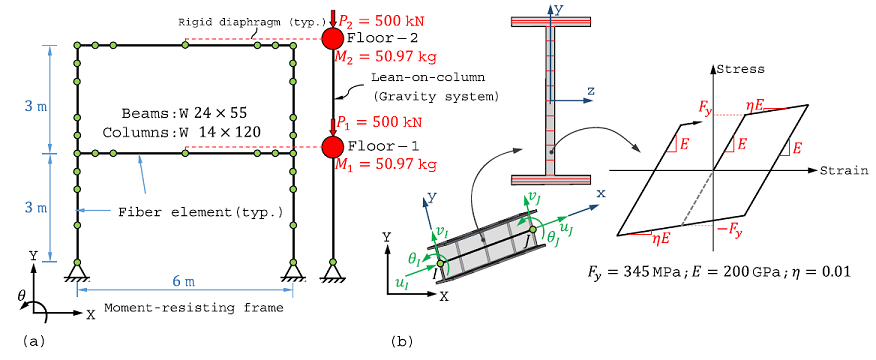

clear; clc; close all;

opsMAT = OpenSeesMatlab;
ops = opsMAT.opensees;
opsvis = opsMAT.vis;

### Units

%% ------------------------------------------------------------------------
%  Units
% -------------------------------------------------------------------------
m    = 1.0;              % meter
KN   = 1.0;              % kilo-Newton
sec  = 1.0;              % second
inch = 0.0254*m;         % inch

kg = KN*(sec^2)/m;       % derived mass unit
g  = 9.81*(m/sec^2);     % gravitational acceleration

### Earthquake record

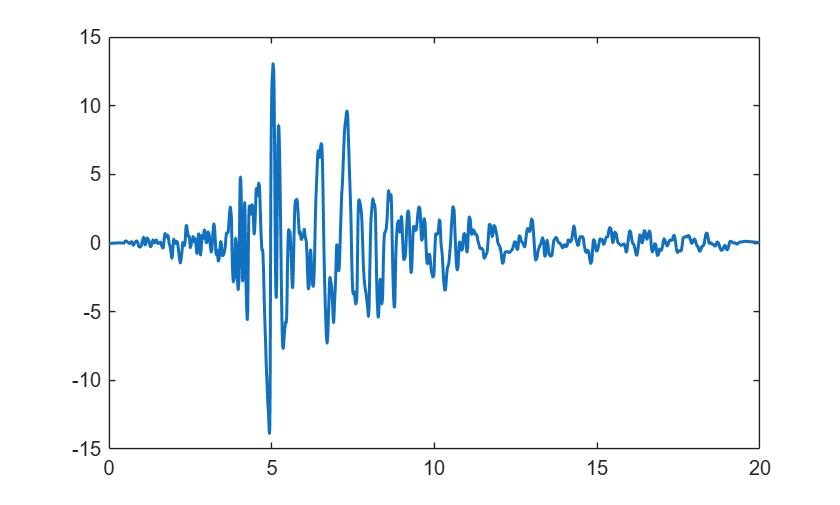

%% ------------------------------------------------------------------------
%  Earthquake record
% -------------------------------------------------------------------------
dt = 0.01*sec;

recordFile = 'utils/RSN960_NORTHR_LOS270.AT2';
if ~isfile(recordFile)
    error('Ground-motion file not found: %s', recordFile);
end

rawMotion = readmatrix(recordFile, 'FileType', 'text', 'NumHeaderLines', 4);
rawMotion = rawMotion.';
rawMotion = rawMotion(:);
rawMotion = rawMotion(~isnan(rawMotion));

accel = rawMotion*3*g;
timeVec = (0:numel(accel)-1)'*dt;

figure;
plot(timeVec, accel, 'LineWidth', 1.5);

### Model definition

%% ------------------------------------------------------------------------
%  Model definition
% -------------------------------------------------------------------------
ops.wipe();
ops.model('basic', '-ndm', 2, '-ndf', 3);

%% ------------------------------------------------------------------------
%  Geometry
% -------------------------------------------------------------------------
node_coords = [ ...
    0,   0;
    6,   0;
    0,   1;
    6,   1;
    0,   2;
    6,   2;
    0,   2.5;
    6,   2.5;
    0,   3;
    0.5, 3;
    1,   3;
    3,   3;
    5,   3;
    5.5, 3;
    6,   3;
    0,   3.5;
    6,   3.5;
    0,   4;
    6,   4;
    0,   5;
    6,   5;
    0,   5.5;
    6,   5.5;
    0,   6;
    0.5, 6;
    1,   6;
    3,   6;
    5,   6;
    5.5, 6;
    6,   6] * m;

connectivity = [ ...
     1,  3;
     3,  5;
     5,  7;
     7,  9;
     9, 10;
    10, 11;
    11, 12;
    12, 13;
    13, 14;
    14, 15;
    15,  8;
     8,  6;
     6,  4;
     4,  2;
     9, 16;
    16, 18;
    18, 20;
    20, 22;
    22, 24;
    24, 25;
    25, 26;
    26, 27;
    27, 28;
    28, 29;
    29, 30;
    30, 23;
    23, 21;
    21, 19;
    19, 17;
    17, 15];

nel = size(connectivity, 1);

all_the_beams = [5:10, 20:25];
all_the_cols  = setdiff(1:nel, all_the_beams);

%% ------------------------------------------------------------------------
%  Sections and material
% -------------------------------------------------------------------------
sections.W24x55.d  = 23.57*inch;
sections.W24x55.tw = 0.395*inch;
sections.W24x55.bf = 7.005*inch;
sections.W24x55.tf = 0.505*inch;
sections.W24x55.A  = 16.2*(inch^2);
sections.W24x55.I1 = 1350*(inch^4);
sections.W24x55.I2 = 29.1*(inch^4);

sections.W14x120.d  = 14.48*inch;
sections.W14x120.tw = 0.590*inch;
sections.W14x120.bf = 14.670*inch;
sections.W14x120.tf = 0.940*inch;
sections.W14x120.A  = 35.3*(inch^2);
sections.W14x120.I1 = 1380*(inch^4);
sections.W14x120.I2 = 495*(inch^4);

leaning_col.A  = 9.76e-2*m^2;
leaning_col.I1 = 7.125e-4*m^4;

F_y = 345000*(KN/m^2);   % yield strength
E_0 = 2e8*(KN/m^2);      % initial elastic tangent
eta = 0.01;              % strain-hardening ratio
rho = 7850*(kg/m^3);     % mass density

lumped_mass = 50.97*kg;  % seismic floor mass
P_1 = 500*KN;            % nodal gravity load

%% ------------------------------------------------------------------------
%  Add nodes
% -------------------------------------------------------------------------
for n = 1:size(node_coords, 1)
    ops.node(n, node_coords(n, 1), node_coords(n, 2));
end

% Fictitious leaning-column nodes
ops.node(100, 7.0, 0.0);
ops.node(101, 7.0, 3.0, '-mass', lumped_mass, 1.0e-5, 1.0e-5);
ops.node(102, 7.0, 6.0, '-mass', lumped_mass, 1.0e-5, 1.0e-5);

%% ------------------------------------------------------------------------
%  Materials and sections
% -------------------------------------------------------------------------
ops.uniaxialMaterial('Steel01', 1, F_y, E_0, eta);

% Beam section
ops.section('WFSection2d', 1, 1, ...
    sections.W24x55.d, sections.W24x55.tw, ...
    sections.W24x55.bf, sections.W24x55.tf, 10, 3);

% Column section
ops.section('WFSection2d', 2, 1, ...
    sections.W14x120.d, sections.W14x120.tw, ...
    sections.W14x120.bf, sections.W14x120.tf, 10, 3);

%% ------------------------------------------------------------------------
%  Boundary conditions
% -------------------------------------------------------------------------
baseNodes = [1, 2, 100];
for i = 1:numel(baseNodes)
    ops.fix(baseNodes(i), 1, 1, 0);
end

% Rigid floor diaphragm in the horizontal direction
ops.equalDOF(12, 101, 1);
ops.equalDOF(27, 102, 1);

%% ------------------------------------------------------------------------
%  Transformations and beam integration
% -------------------------------------------------------------------------
ops.geomTransf('Linear', 1);   % beams and MRF members
ops.geomTransf('PDelta', 2);   % leaning columns

ops.beamIntegration('Lobatto', 1, 1, 5);   % beam section integration
ops.beamIntegration('Lobatto', 2, 2, 5);   % column section integration

%% ------------------------------------------------------------------------
%  Add elements
% -------------------------------------------------------------------------
% Beams
for i = 1:numel(all_the_beams)
    e = all_the_beams(i);
    iNode = connectivity(e, 1);
    jNode = connectivity(e, 2);
    ops.element('dispBeamColumn', e, iNode, jNode, 1, 1, ...
        '-cMass', rho*sections.W24x55.A);
end

% Columns
for i = 1:numel(all_the_cols)
    e = all_the_cols(i);
    iNode = connectivity(e, 1);
    jNode = connectivity(e, 2);
    ops.element('dispBeamColumn', e, iNode, jNode, 1, 2, ...
        '-cMass', rho*sections.W14x120.A);
end

% Leaning columns
ops.element('elasticBeamColumn', nel + 1, 100, 101, ...
    leaning_col.A, E_0, leaning_col.I1, 2);
ops.element('elasticBeamColumn', nel + 2, 101, 102, ...
    leaning_col.A, E_0, leaning_col.I1, 2);

[OpenSeesMatlab] Model summary
  Nodes: 33
  Beam elements: 32
  MP constraints: 2


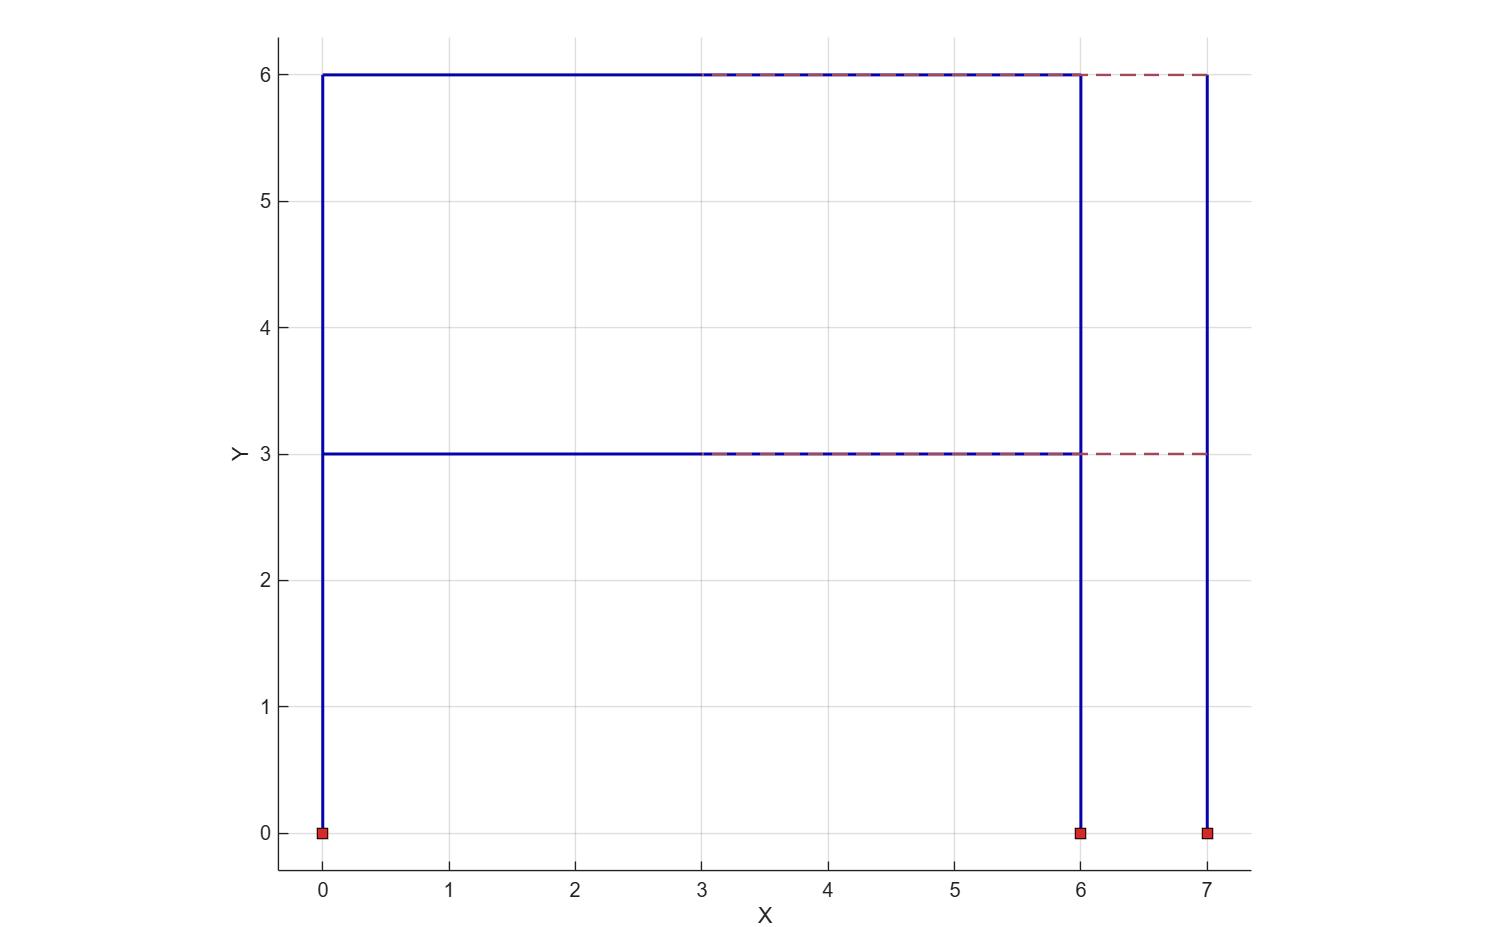

opsvis.plotModel();

### Rayleigh damping

%% ------------------------------------------------------------------------
%  Rayleigh damping: 2% damping in the first two modes
% -------------------------------------------------------------------------
lambda = ops.eigen('-fullGenLapack', 2);
omega = sqrt(lambda(:));
periods = 2*pi ./ omega;

disp('First two periods:');

First two periods:


disp(periods.');

    0.6169    0.1174




zeta = [0.02; 0.02];
A_damp = [1/(2*omega(1)), omega(1)/2;
          1/(2*omega(2)), omega(2)/2];
coeff = A_damp \ zeta;
a_m = coeff(1);
b_k = coeff(2);

% Rayleigh damping based on initial stiffness
ops.rayleigh(a_m, 0.0, b_k, 0.0);

### Gravity analysis

%% ------------------------------------------------------------------------
%  Gravity analysis
% -------------------------------------------------------------------------
ops.timeSeries('Linear', 1);
ops.pattern('Plain', 1, 1);
ops.load(101, 0.0, -P_1, 0.0);
ops.load(102, 0.0, -P_1, 0.0);

ops.constraints('Transformation');
ops.numberer('RCM');
ops.system('ProfileSPD');
ops.test('NormUnbalance', 1.0e-8, 100);
ops.algorithm('Newton');
ops.integrator('LoadControl', 0.1);
ops.analysis('Static');

okGravity = ops.analyze(10);
fprintf('Gravity analysis return code: %d\n', okGravity);

Gravity analysis return code: 0


### Time-history analysis

%% ------------------------------------------------------------------------
%  Time-history analysis
% -------------------------------------------------------------------------
ops.loadConst('-time', 0.0);
ops.wipeAnalysis();

% Uniform base excitation in the global X direction.
% The acceleration values are already scaled by 3g and written to file.
ops.timeSeries('Path', 2, '-dt', dt, '-values', accel);
ops.pattern('UniformExcitation', 2, 1, '-accel', 2);

ops.constraints('Plain');
ops.numberer('RCM');
ops.system('ProfileSPD');
ops.test('NormUnbalance', 1.0e-8, 100);
ops.algorithm('Newton');
ops.integrator('Newmark', 0.5, 0.25);
ops.analysis('Transient');

nSteps = numel(accel);
time_lst = zeros(nSteps, 1);
d_lst    = zeros(nSteps, 1);

for i = 1:nSteps
    ok = ops.analyze(1, dt);
    if ok ~= 0
        warning('Transient analysis failed at step %d, time %.4f sec, return code %d.', ...
            i, ops.getTime(), ok);
        time_lst = time_lst(1:i-1);
        d_lst = d_lst(1:i-1);
        break;
    end

    time_lst(i) = ops.getTime();
    d_lst(i) = ops.nodeDisp(27, 1);
end

### Plot roof displacement response

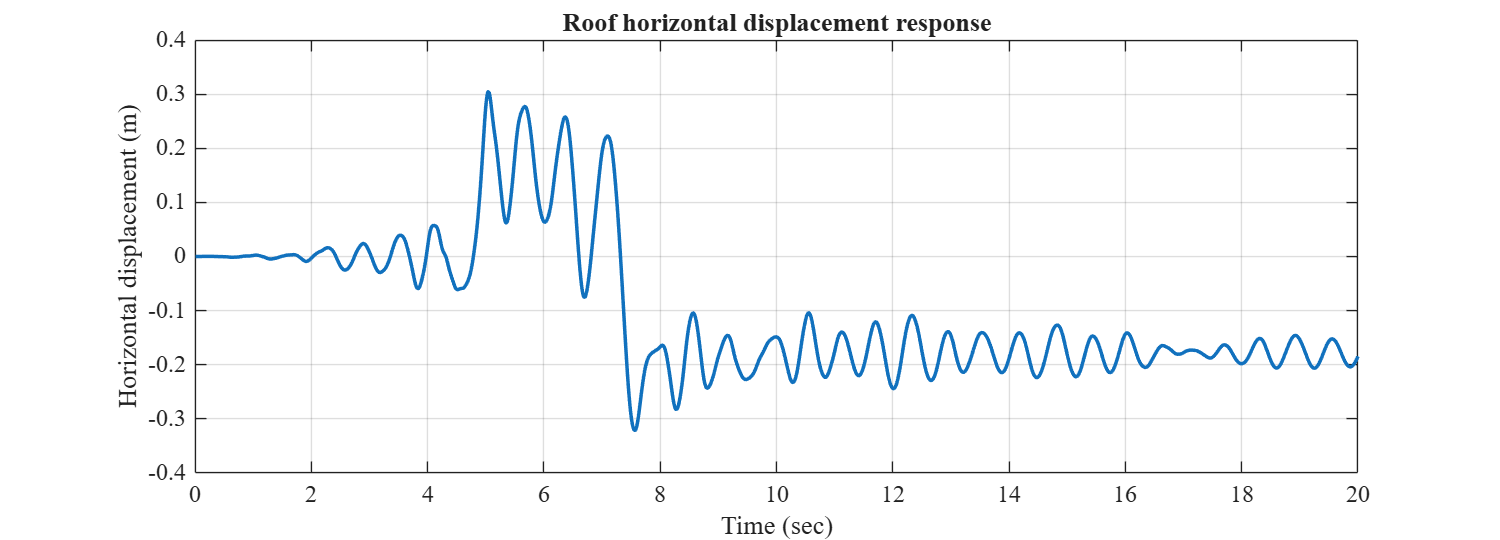

%% ------------------------------------------------------------------------
%  Plot roof displacement response
% -------------------------------------------------------------------------
figure('Color', 'w', 'Position', [100, 100, 1000, 360]);
plot(time_lst, d_lst, 'LineWidth', 1.75);
grid on; box on;
xlabel('Time (sec)', 'FontName', 'Times New Roman', 'FontSize', 13);
ylabel('Horizontal displacement (m)', 'FontName', 'Times New Roman', 'FontSize', 13);
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);
title('Roof horizontal displacement response', 'FontName', 'Times New Roman', 'FontSize', 13);

% Uncomment the following line if you want to clear the OpenSees domain at end.
% ops.wipe();